rng(1);  % Reproducible results

%% 1. MODEL SETTINGS

N = 20;
numSteps = 15;
numSimulations = 30;
cellAreaHa = 0.25;

pDisturbed = 0.40;
pUndisturbed = 0.10;

disturbanceLevels = [0, 0.30, 1];

scenarioNames = {
    'All undisturbed'
    '30% disturbed'
    'All disturbed'
};

strategyNames = {
    'No clearing'
    'Once-off clearing'
    'Repeated clearing'
};

numScenarios = length(disturbanceLevels);
numStrategies = length(strategyNames);

% Clearing assumptions
clearFraction = 0.50;
onceOffStep = 8;
repeatedSteps = [3, 6, 9, 12, 15];

% Initial invaded patch
initialRows = 10:11;
initialCols = 10:11;

% 2. STORAGE

% Dimensions: habitat scenario x strategy x simulation
resultsHa = zeros(numScenarios, numStrategies, ...
    numSimulations);

% 3. RUN SIMULATIONS

for s = 1:numScenarios

    % Generate one fixed habitat map per scenario
    numCells = N * N;
    numDisturbed = round(disturbanceLevels(s) * numCells);
    disturbedMap = false(N, N);
    if numDisturbed > 0
        selectedCells = randperm(numCells, numDisturbed);
        disturbedMap(selectedCells) = true;
    end

    for strategy = 1:numStrategies

        for sim = 1:numSimulations

            % Initialise landscape
            CAgrid = zeros(N, N);
            CAgrid(initialRows, initialCols) = 1;

            % Simulate invasion
            for t = 1:numSteps

                newGrid = CAgrid;

                for r = 1:N
                    for c = 1:N

                        if CAgrid(r,c) == 0

                            % Check four orthogonal neighbours
                            hasInvadedNeighbour = false;

                            if r > 1 && CAgrid(r-1,c) == 1
                                hasInvadedNeighbour = true;
                            end

                            if r < N && CAgrid(r+1,c) == 1
                                hasInvadedNeighbour = true;
                            end

                            if c > 1 && CAgrid(r,c-1) == 1
                                hasInvadedNeighbour = true;
                            end

                            if c < N && CAgrid(r,c+1) == 1
                                hasInvadedNeighbour = true;
                            end

                            if hasInvadedNeighbour

                                if disturbedMap(r,c) == 1
                                    p = pDisturbed;
                                else
                                    p = pUndisturbed;
                                end

                                if rand < p
                                    newGrid(r,c) = 1;
                                end
                            end
                        end
                    end
                end

                % Update spread simultaneously
                CAgrid = newGrid;

                %% CLEARING RULES

                shouldClear = false;

                % Strategy 1: No clearing
                if strategy == 1
                    shouldClear = false;

                % Strategy 2: One-off clearing at step 8
                elseif strategy == 2
                    if t == onceOffStep
                        shouldClear = true;
                    end

                % Strategy 3: Repeated clearing
                elseif strategy == 3
                    if ismember(t, repeatedSteps)
                        shouldClear = true;
                    end
                end

                % Randomly remove 50% of invaded cells
                if shouldClear

                    invadedIndices = find(CAgrid == 1);
                    numInvaded = length(invadedIndices);

                    numToClear = round( ...
                        clearFraction * numInvaded);

                    if numToClear > 0

                        order = randperm(numInvaded);
                        clearedIndices = invadedIndices( ...
                            order(1:numToClear));

                        CAgrid(clearedIndices) = 0;
                    end
                end

            end

            % Record final invaded area
            invadedCells = sum(CAgrid(:) == 1);

            resultsHa(s, strategy, sim) = ...
                invadedCells * cellAreaHa;

        end
    end
end

%% 4. SUMMARY STATISTICS

meanArea = zeros(numScenarios, numStrategies);
stdArea = zeros(numScenarios, numStrategies);
minArea = zeros(numScenarios, numStrategies);
maxArea = zeros(numScenarios, numStrategies);

for s = 1:numScenarios
    for strategy = 1:numStrategies

        values = squeeze(resultsHa(s, strategy, :));

        meanArea(s, strategy) = mean(values);
        stdArea(s, strategy) = std(values);
        minArea(s, strategy) = min(values);
        maxArea(s, strategy) = max(values);

    end
end

% Display results in a table
Scenario = {};
Strategy = {};
MeanHa = [];
StdHa = [];
MinHa = [];
MaxHa = [];

for s = 1:numScenarios
    for strategy = 1:numStrategies

        Scenario{end+1,1} = scenarioNames{s};
        Strategy{end+1,1} = strategyNames{strategy};

        MeanHa(end+1,1) = meanArea(s,strategy);
        StdHa(end+1,1) = stdArea(s,strategy);
        MinHa(end+1,1) = minArea(s,strategy);
        MaxHa(end+1,1) = maxArea(s,strategy);

    end
end

summaryTable = table(Scenario, Strategy, ...
    MeanHa, StdHa, MinHa, MaxHa);

disp('CLEARING EXPERIMENT RESULTS');

CLEARING EXPERIMENT RESULTS


disp(summaryTable);

         Scenario                Strategy           MeanHa      StdHa     MinHa    MaxHa
    ___________________    _____________________    _______    _______    _____    _____

    {'All undisturbed'}    {'No clearing'      }      6.375      2.119        3     10.5
    {'All undisturbed'}    {'Once-off clearing'}       4.95      1.529      2.5     8.75
    {'All undisturbed'}    {'Repeated clearing'}    0.53333     0.4086        0     1.75
    {'30% disturbed'  }    {'No clearing'      }     11.625     2.7361        6    18.25
    {'30% disturbed'  }    {'Once-off clearing'}       8.95     2.5734     3.25    14.25
    {'30% disturbed'  }    {'Repeated clearing'}     1.6417    0.78697     0.25     3.75
    {'All disturbed'  }    {'No clearing'      }     53.075      4.592    45.25    

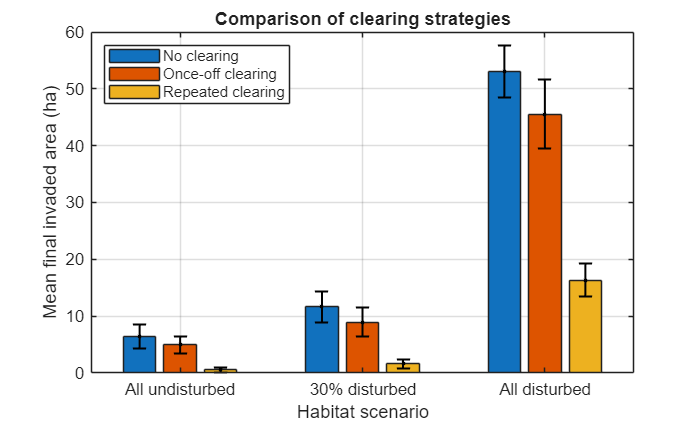


%% 5. PLOT CLEARING STRATEGIES

figure;

b = bar(meanArea);
hold on;
for k = 1:numStrategies
    x = b(k).XEndPoints;
    errorbar(x, meanArea(:,k), stdArea(:,k), ...
        'k.', 'LineWidth', 1.2, 'CapSize', 8);
end
set(gca, 'XTick', 1:numScenarios, ...
    'XTickLabel', scenarioNames);

xlabel('Habitat scenario');
ylabel('Mean final invaded area (ha)');

title('Comparison of clearing strategies');

legend([b(1), b(2), b(3)], {'No clearing', 'Once-off clearing', 'Repeated clearing'}, ...
    'Location', 'northwest');

grid on;
hold off;


%% 6. CALCULATE REDUCTION RELATIVE TO NO CLEARING

% Reduction (%) = (baseline - clearing) / baseline * 100
% Strategy 1 is the no-clearing baseline.

reductionPercent = zeros(numScenarios, numStrategies);

for s = 1:numScenarios

    baseline = meanArea(s,1);

    for strategy = 1:numStrategies

        if baseline > 0
            reductionPercent(s,strategy) = ...
                (baseline - meanArea(s,strategy)) ...
                / baseline * 100;
        else
            reductionPercent(s,strategy) = NaN;
        end
    end
end

reductionTable = table( ...
    scenarioNames, ...
    reductionPercent(:,1), ...
    reductionPercent(:,2), ...
    reductionPercent(:,3), ...
    'VariableNames', { ...
    'HabitatScenario', ...
    'NoClearingReductionPercent', ...
    'OnceOffReductionPercent', ...
    'RepeatedReductionPercent'});

disp('REDUCTION RELATIVE TO NO CLEARING (%)');

REDUCTION RELATIVE TO NO CLEARING (%)


disp(reductionTable);

      HabitatScenario      NoClearingReductionPercent    OnceOffReductionPercent    RepeatedReductionPercent
    ___________________    __________________________    _______________________    ________________________

    {'All undisturbed'}                0                         22.353                      91.634         
    {'30% disturbed'  }                0                         23.011                      85.878         
    {'All disturbed'  }                0                         14.288                      69.242         



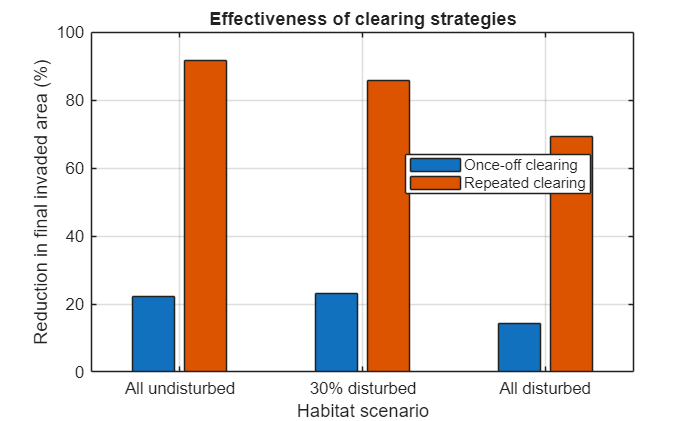


%% 7. PLOT PERCENTAGE REDUCTION

figure;

%Exclude no clearing because its baseline 
bar(reductionPercent(:, 2:3));

set(gca, 'XTick', 1:numScenarios, ...
    'XTickLabel', scenarioNames);

xlabel('Habitat scenario');
ylabel('Reduction in final invaded area (%)');

title('Effectiveness of clearing strategies');

legend({'Once-off clearing', 'Repeated clearing'}, ...
    'Location', 'best');

ylim([0 100]);
grid on;

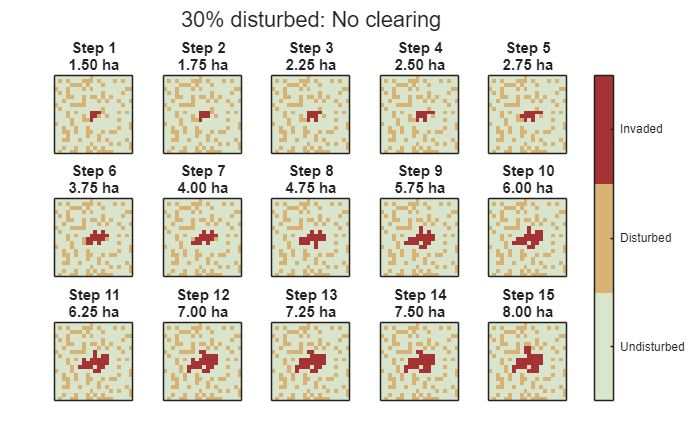

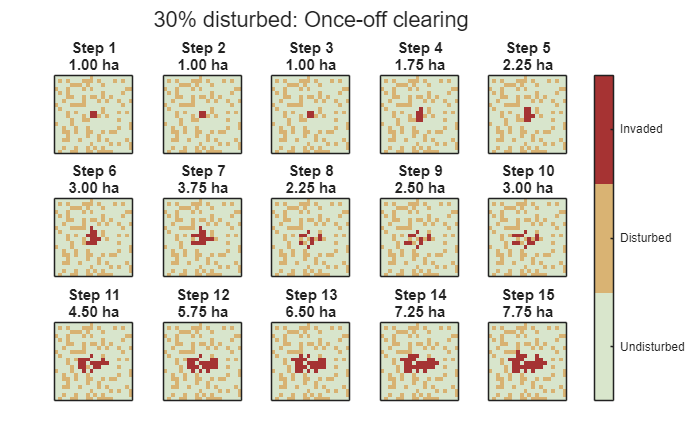

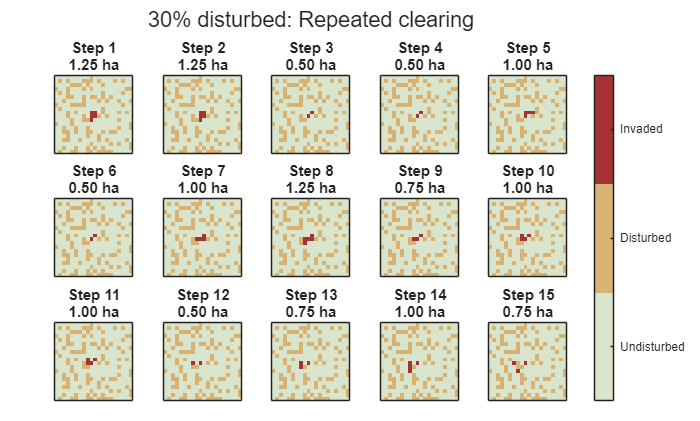

% 8. Visualise
mapColours = [
    0.85 0.90 0.80
    0.85 0.70 0.45
    0.65 0.20 0.20
    ];
for strategy = 1:numStrategies
    figure('Color', 'w', 'Name', strategyNames{strategy});
    tiledlayout(3, 5, ...
        'TileSpacing', 'compact', ...
        'Padding', 'compact');

    for t = 1:numSteps

        nexttile;

        % Start with the habitat map
        displayGrid = ones(N, N);

        displayGrid(mapDisturbedMap) = 2;

        % Show currently invaded cells
        currentGrid = mapSnapshots(:,:,t,strategy);
        displayGrid(currentGrid == 1) = 3;

        imagesc(displayGrid);

        colormap(mapColours);
        clim([0.5 3.5]);

        axis equal tight;
        set(gca, 'XTick', [], 'YTick', []);

        % Calculate current invaded area
        invadedCells = sum(currentGrid(:) == 1);
        invadedArea = invadedCells * cellAreaHa;

        title(sprintf('Step %d\n%.2f ha', ...
            t, invadedArea), ...
            'FontSize', 9);

    end

    % Overall figure title
    sgtitle(sprintf('%s: %s', ...
        scenarioNames{mapScenario}, ...
        strategyNames{strategy}));

    % Legend
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Ticks = [1 2 3];
    cb.TickLabels = { ...
        'Undisturbed', ...
        'Disturbed', ...
        'Invaded'};

end

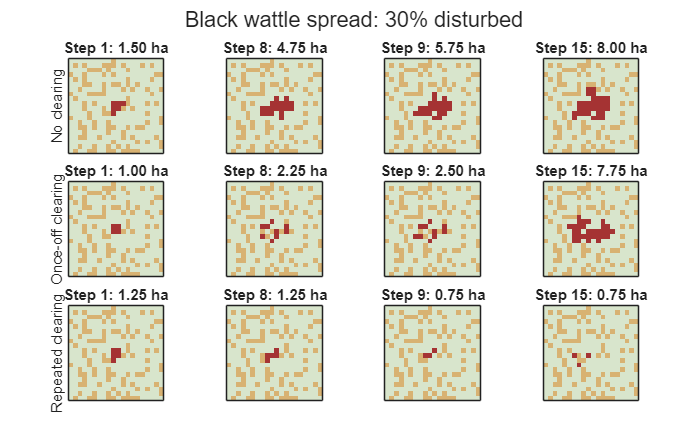


%% SIMPLE SPATIAL MAP COMPARISON

selectedSteps = [1 8 9 15];

mapColours = [
    0.85 0.90 0.80   % Undisturbed
    0.85 0.70 0.45   % Disturbed
    0.65 0.20 0.20   % Invaded
];

figure('Color','w');

tiledlayout(3,4, ...
    'TileSpacing','compact', ...
    'Padding','compact');

for strategy = 1:numStrategies

    for j = 1:length(selectedSteps)

        t = selectedSteps(j);

        nexttile;

        displayGrid = ones(N,N);
        displayGrid(mapDisturbedMap) = 2;

        currentGrid = mapSnapshots(:,:,t,strategy);
        displayGrid(currentGrid == 1) = 3;

        imagesc(displayGrid);

        colormap(mapColours);
        clim([0.5 3.5]);

        axis equal tight;
        set(gca,'XTick',[],'YTick',[]);

        invadedArea = sum(currentGrid(:)) ...
            * cellAreaHa;

        title(sprintf('Step %d: %.2f ha', ...
            t, invadedArea),'FontSize',9);

        if j == 1
            ylabel(strategyNames{strategy});
        end

    end
end

sgtitle(sprintf('Black wattle spread: %s', ...
    scenarioNames{mapScenario}));